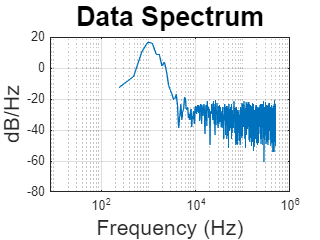

clearvars
data = readtable('./ADC_Data/11-24-Python-Pull-Data/SIN_2000Hz_950mV---CLK_1MHz_50%.csv');
data_dec = table2array(data);
data_dec = data_dec(data_dec ~= 0);
data_bin = dec2bin(data_dec);
data_EOC = str2num(data_bin(:,1));
data_Code = str2num(data_bin(:,2:10));
data_NewCode = size(length(data_Code),1);

rising_edge_indices = find(diff(data_EOC) == 1) + 1;

for i = 1:length(rising_edge_indices)
    index = rising_edge_indices(i);
    data_NewCode(i,1) = data_Code(index); 
end
data_NewDec = bin2dec(num2str(data_NewCode));

Fs=1e6;
num_segments=1;
f_signal =  2e3;
f_s = Fs;
BW =500e3;
sample_size=2^12;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);

fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);

@Freq = 2000.000, SNR = 16.905 dB, SNDR = -18.737 dB, SFDR = 18.466 dB, HD2 = 18.466 and HD3 = 18.748


set(gcf,'color','w')

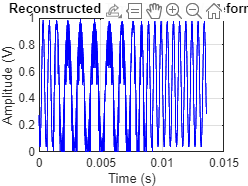


% Parameters
fs = 1e6;                 % Sampling rate in Hz
N = length(data_NewDec);                  % Number of samples
bit_depth = 9;            % ADC bit resolution
V_min = 0;              % Minimum input voltage
V_max = 1;               % Maximum input voltage

% Map codes to voltage
voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;

% Create time axis
t = (0:N-1) / fs;

% Plot the reconstructed waveform
figure;
plot(t, voltages, 'b');
title('Reconstructed Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

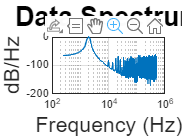

Fs=1e6;
num_segments=1;
f_signal =  2e3;
f_s = Fs;
BW =500e3;
sample_size=2^12;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);

fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);

@Freq = 2000.000, SNR = 50.123 dB, SNDR = 50.059 dB, SFDR = 69.653 dB, HD2 = 69.653 and HD3 = 81.660


set(gcf,'color','w')

Fs = 44100;         % Sampling frequency in Hz (44.1 kHz is common for audio)
f = 2000;           % Frequency of sine wave in Hz (2 kHz)
duration = 0.01;    % Duration of the signal in seconds (e.g., 10 ms)

% Time vector
t = 0:1/Fs:duration; % Time vector from 0 to duration with step size 1/Fs

% Sine wave
y = sin(2*pi*f*t);

% Parameters
Fs = 1e6;         % Sampling frequency in Hz
f = 2000;           % Frequency of sine wave in Hz
duration = 0.01;    % Duration of the signal in seconds
bitDepth = 8;       % Bit depth for quantization (e.g., 8-bit)

% Time vector
t = 0:1/Fs:duration; % Time vector

% Generate sine wave
y = sin(2*pi*f*t);

% Quantization
maxAmplitude = (2^(bitDepth - 1)) - 1; % Maximum amplitude for given bit depth
y_quantized = round(y * maxAmplitude); % Scale and round to integer values
data_NewDec = y_quantized';